遗传算法案例

山东理工大学 数学院  周世祥 shixiangbupt@qq.com

仙农，决策树，冯诺依曼，图灵

np

神经网络--仿真人脑

SVM支持向量机

通用人工智能

瓶颈

全局优化工具箱提供了一些函数, 用于寻找包含多个极大值或极小值的问题的全局解。工具箱包括全局搜索、多初始点、模式搜索、遗传算法、多目标遗传算法、模拟退火和粒子群求解。您可以使用这些求解器解决优化问题。通过设置选项和自定义创建、更新和搜索功能, 可以提高规划求解的有效性。您可以使用自定义数据类型与遗传算法和模拟退火求解来表示不容易用标准数据类型表示的问题。混合函数选项使您可以通过在第一个之后应用第二个求解器来改进解决方案。

参数：

染色体位串长为$l$，群体规模为n,交叉概率为$p_c$，变异概率为$p_m$

串长的取决于问题解的精度，但需要的运行时间也越长。群体规模与所求问题的非线性程度有关，非线性越大，n越大。交叉概率太高，群体中新结构的引入就越快，同时优良基因丢失的就越高，太低，可能导致搜索阻滞，一般$p_c =0\ldotp 6~1$；变异概率是群体多样性的保证，太高就变成随机搜索，太低可能使某些基因位过早丢失信息而无法恢复，一般$p_m =0\ldotp 005~0\ldotp 05$。

doc  ga

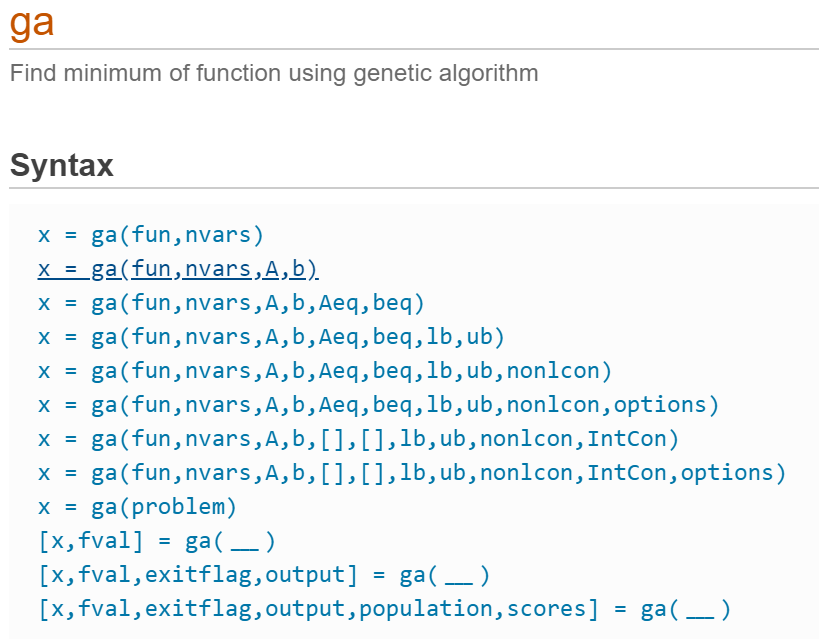

`[x,fval,exitflag,output,population,scores] =ga(fun,nvars,A,b,[],[],lb,ub,nonlcon,IntCon,options) `

`fun适应度函数句柄，nvars目标函数自变量的个数，options算法属性设置，exitflag为算法停止原因。`

`参数解释：`

`% x         为所求得的最小值点，而不是最小值`

`% fval      为对应最小值点x处的最小值`

`% fun       为目标函数。注：若fun为m文件，要用通过句柄@进行引用`

`% nvars     为目标函数的未知数个数`

`% A         线性约束条件：不等式中的系数`

`% b         线性约束条件：不等式右端的值`

`%Aeq        线性约束条件：等式中的系数`

`%beq        线性约束条件：等式右端的值`

`%lb            x的下界`

`%ub            x的上界`

`%nonlcon    非线性约束条件：在MathWorks提供的文档中，是通过函数句柄的方法传入参数，对于约束条件{c<=0;ceq=0}，构造一个function，使[c,ceq]作为返回值，c = *(x);ceq = **(x)的形式，nonlcon = @function;`

`%options    options的用法，相对较为复杂， `

%IntCon        整形变量，输入值为变量的位置

`例一：`

$\left\lbrack \begin{array}{cc}
1 & 1\\
-1 & 2\\
2 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \le \left\lbrack \begin{array}{c}
2\\
2\\
3
\end{array}\right\rbrack$,$x_1 ,x_2 \ge 0$,求函数的最小值。

clear all;
A = [1 1; -1 2; 2 1];
b = [2; 2; 3];
lb = zeros(2,1);
[x,fval,exitflag,output] = ga(@lincontest6,2,A,b,[],[],lb)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =    0.667000002830028   1.333999996543003


fval =   -8.225777493723154


exitflag =      1


output = 包含以下字段的 struct :
      problemtype: 'linearconstraints'
         rngstate: [1×1 struct]
      generations: 183
        funccount: 8654
          message: 'Optimization terminated: average change in the fitness value less than options.FunctionTolerance.'
    maxconstraint: 9.999993730311907e-04


`lincontest6`` A quadratic objective function (from Optimization Toolbox)`

`function y = lincontest6(x)`

`%LINCONTEST6 A quadratic objective function (from Optimization Toolbox)`

`%   Copyright 2003-2007 The MathWorks, Inc. `

`p1=0.5;`

`p2=6.0;`

`y = p1*x(1)^2 + x(2)^2 -x(1)*x(2) -2*x(1) - p2*x(2);`

`%Derivative of the function above`

`% dy = [(2*p1*x(1) - x(2) -2);(2*x(2) -x(1) -p2)];`

`测试函数`

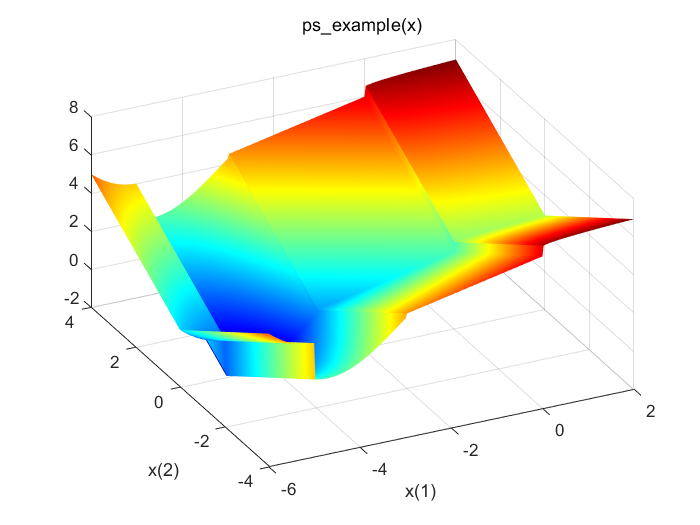

xi = linspace(-6,2,300);
yi = linspace(-4,4,300);
[X,Y] = meshgrid(xi,yi);
Z = ps_example([X(:),Y(:)]);
Z = reshape(Z,size(X));
surf(X,Y,Z,'MeshStyle','none')
colormap 'jet'
view(-26,43)
xlabel('x(1)')
ylabel('x(2)')
title('ps\_example(x)')

x = ga(@ps_example,2)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =   -4.895830981522517   0.088161265181042


例题3：

% function y=M9_3(x)
% y=(cos(x(1)^2+x(2)^3)-0.1)/(1+0.3*(x(1)^2+x(2)^2)^2)+3;
% end



[x,fval,exitflag,output]=ga(@M9_3,2)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =    0.013372945810713  -1.431900279936279


fval =    2.522912494012468


exitflag =      1


output = 包含以下字段的 struct :
      problemtype: 'unconstrained'
         rngstate: [1×1 struct]
      generations: 102
        funccount: 4847
          message: 'Optimization terminated: average change in the fitness value less than options.FunctionTolerance.'
    maxconstraint: []


求解TSP

% function varargout = mtsp_ga(xy,dmat,salesmen,min_tour,pop_size,num_iter,show_prog,show_res)
% % 输入：
% %     XY：各个城市坐标的N*2矩阵，N为城市的个数
% %     DMAT：各个城市之间的距离矩阵
% %     SALESMEN ：旅行商人数
% %     MIN_TOUR：每个人所经过的最少城市点
% %     POP_SIZE：种群大小
% %     NUM_ITER：迭代次数
% % 输出：
% %     最优路线
% %     总距离
%  % 初始化
% nargs = 8;
% for k = nargin:nargs-1
%     switch k
%         case 0
%             xy = 10*rand(40,2);
%         case 1
%             N = size(xy,1);
%             a = meshgrid(1:N);
%             dmat = reshape(sqrt(sum((xy(a,:)-xy(a',:)).^2,2)),N,N);
%         case 2
%             salesmen = 5; %     SALESMEN：人数
%         case 3
%             min_tour = 3; %     MIN_TOUR :每个人所经过的最少城市点
%         case 4
%             pop_size = 80; % POP_SIZE：种群大小
%         case 5
%             num_iter = 5e3; % NUM_ITER：迭代次数
%         case 6
%             show_prog = 1;
%         case 7
%             show_res = 1;
%         otherwise
%     end
% end
% %调整输入数据 
% N = size(xy,1);
% [nr,nc] = size(dmat);
% if N ~= nr || N ~= nc
%     error('Invalid XY or DMAT inputs!')
% end
% n = N;
%  %约束条件
% salesmen = max(1,min(n,round(real(salesmen(1)))));
% min_tour = max(1,min(floor(n/salesmen),round(real(min_tour(1)))));
% pop_size = max(8,8*ceil(pop_size(1)/8));
% num_iter = max(1,round(real(num_iter(1))));
% show_prog = logical(show_prog(1));
% show_res = logical(show_res(1));
%  % 路线的初始化
% num_brks = salesmen-1;
% dof = n - min_tour*salesmen;       
% addto = ones(1,dof+1);
% for k = 2:num_brks
%     addto = cumsum(addto);
% end
% cum_prob = cumsum(addto)/sum(addto);
%  % 种群初始化
% pop_rte = zeros(pop_size,n);          
% pop_brk = zeros(pop_size,num_brks);   
% for k = 1:pop_size
%     pop_rte(k,:) = randperm(n);
%     pop_brk(k,:) = randbreaks();
% end
% tmp_pop_rte = zeros(8,n);
% tmp_pop_brk = zeros(8,num_brks);
% new_pop_rte = zeros(pop_size,n);
% new_pop_brk = zeros(pop_size,num_brks);
%  %图形中各个路线的颜色
% clr = [1 0 0; 0 0 1; 0.67 0 1; 0 1 0; 1 0.5 0];
% if salesmen > 5
%     clr = hsv(salesmen);
% end
%  % 遗传算法实现
% global_min = Inf;
% total_dist = zeros(1,pop_size);
% dist_history = zeros(1,num_iter);
% if show_prog
%     pfig = figure('Name','MTSP_GA | Current Best Solution','Numbertitle','off');
% end
% for iter = 1:num_iter
%     for p = 1:pop_size
%         d = 0;
%         p_rte = pop_rte(p,:);
%         p_brk = pop_brk(p,:);
%         rng = [[1 p_brk+1];[p_brk n]]';
%         for s = 1:salesmen
%             d = d + dmat(p_rte(rng(s,2)),p_rte(rng(s,1)));
%             for k = rng(s,1):rng(s,2)-1
%                 d = d + dmat(p_rte(k),p_rte(k+1));
%             end
%         end
%         total_dist(p) = d;
%     end
%     % 种群中的最优路线
%     [min_dist,index] = min(total_dist);
%     dist_history(iter) = min_dist;
%     if min_dist < global_min
%         global_min = min_dist;
%         opt_rte = pop_rte(index,:);
%         opt_brk = pop_brk(index,:);
%         rng = [[1 opt_brk+1];[opt_brk n]]';
%         if show_prog
%             % 画最优路线图
%             figure(pfig);
%             for s = 1:salesmen
%                 rte = opt_rte([rng(s,1):rng(s,2) rng(s,1)]);
%                 plot(xy(rte,1),xy(rte,2),'.-','Color',clr(s,:));
%                 title(sprintf('Total Distance = %1.4f, Iterations = %d',min_dist,iter));
%                 hold on
%             end
%             hold off
%         end
%     end
%    %遗传算法的进程操作 
%     rand_grouping = randperm(pop_size);
%     for p = 8:8:pop_size
%         rtes = pop_rte(rand_grouping(p-7:p),:);
%         brks = pop_brk(rand_grouping(p-7:p),:);
%         dists = total_dist(rand_grouping(p-7:p));
%         [ignore,idx] = min(dists);
%         best_of_8_rte = rtes(idx,:);
%         best_of_8_brk = brks(idx,:);
%         rte_ins_pts = sort(ceil(n*rand(1,2)));
%         I = rte_ins_pts(1);
%         J = rte_ins_pts(2);
%         for k = 1:8 % 产生新的解
%             tmp_pop_rte(k,:) = best_of_8_rte;
%             tmp_pop_brk(k,:) = best_of_8_brk;
%             switch k
%                 case 2 % 选择交叉算子
%                     tmp_pop_rte(k,I:J) = fliplr(tmp_pop_rte(k,I:J));
%                 case 3 %变异算子
%                     tmp_pop_rte(k,[I J]) = tmp_pop_rte(k,[J I]);
%                 case 4 %重排序
%                     tmp_pop_rte(k,I:J) = tmp_pop_rte(k,[I+1:J I]);
%                 case 5 %修改城市点
%                     tmp_pop_brk(k,:) = randbreaks();
%                 case 6 %选择交叉
%                     tmp_pop_rte(k,I:J) = fliplr(tmp_pop_rte(k,I:J));
%                     tmp_pop_brk(k,:) = randbreaks();
%                 case 7 % 变异，修改城市点
%                     tmp_pop_rte(k,[I J]) = tmp_pop_rte(k,[J I]);
%                     tmp_pop_brk(k,:) = randbreaks();
%                 case 8 %重排序，修改城市点
%                     tmp_pop_rte(k,I:J) = tmp_pop_rte(k,[I+1:J I]);
%                     tmp_pop_brk(k,:) = randbreaks();
%                 otherwise 
%             end
%         end
%         new_pop_rte(p-7:p,:) = tmp_pop_rte;
%         new_pop_brk(p-7:p,:) = tmp_pop_brk;
%     end
%     pop_rte = new_pop_rte;
%     pop_brk = new_pop_brk;
% end
%  if show_res
% % 画图
%     figure('Name','MTSP_GA | Results','Numbertitle','off');
%     subplot(2,2,1);
%     plot(xy(:,1),xy(:,2),'k.');
%     title('City Locations');
%     subplot(2,2,2);
%     imagesc(dmat(opt_rte,opt_rte));
%     title('Distance Matrix');
%     subplot(2,2,3);
%     rng = [[1 opt_brk+1];[opt_brk n]]';
%     for s = 1:salesmen
%         rte = opt_rte([rng(s,1):rng(s,2) rng(s,1)]);
%         plot(xy(rte,1),xy(rte,2),'.-','Color',clr(s,:));
%         title(sprintf('Total Distance = %1.4f',min_dist));
%         hold on;
%     end
%     subplot(2,2,4);
%     plot(dist_history,'b','LineWidth',2);
%     title('Best Solution History');
%     set(gca,'XLim',[0 num_iter+1],'YLim',[0 1.1*max([1 dist_history])]);
% end
%  % 结果展示
% if nargout
%     varargout{1} = opt_rte;
%     varargout{2} = opt_brk;
%     varargout{3} = min_dist;
% end
%      % 随机城市点的生成
%     function breaks = randbreaks()
%         if min_tour == 1 
%             tmp_brks = randperm(n-1);
%             breaks = sort(tmp_brks(1:num_brks));
%         else 
%             num_adjust = find(rand < cum_prob,1)-1;
%             spaces = ceil(num_brks*rand(1,num_adjust));
%             adjust = zeros(1,num_brks);
%             for kk = 1:num_brks
%                 adjust(kk) = sum(spaces == kk);
%             end
%             breaks = min_tour*(1:num_brks) + cumsum(adjust);
%         end
%     end
% end


主程序

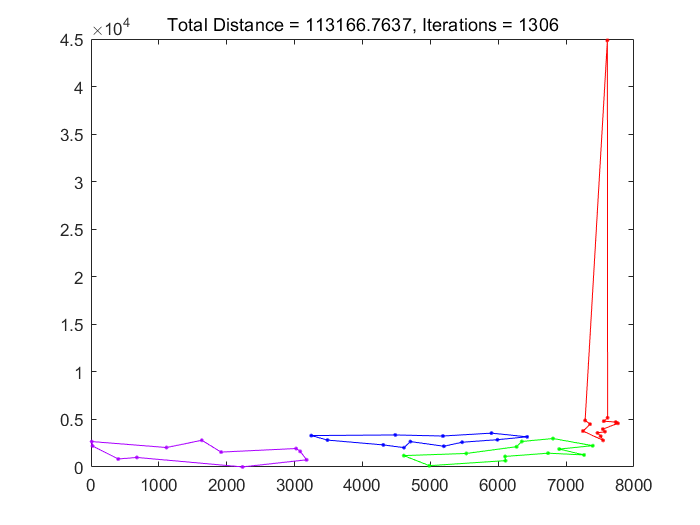

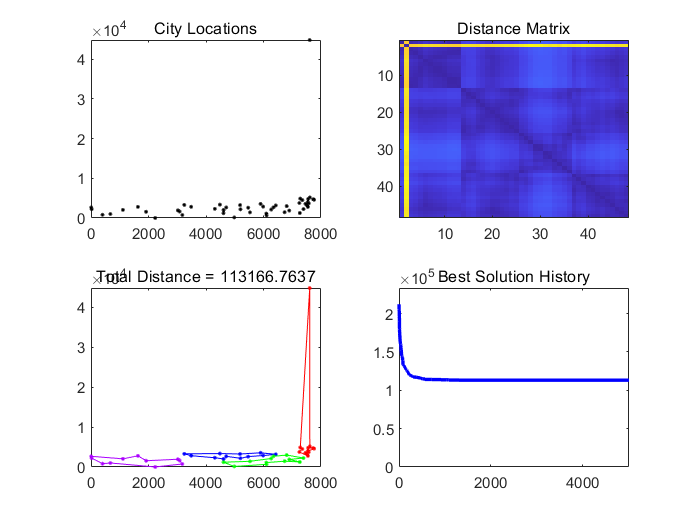

x =     17     6    43    30    36    31    44    18     7    28    37    19    27    25    39    32    21    47    20    33    12    11    23    13    14     5    29     2    26     4    35    45    10    24    42    48     3    34    41    16    22     1     8     9    38    46    15    40


fval =     13    25    36


exitflag =      1.131667636677762e+05


n=48;
xy=[6734 1453;2233 10;5530 1424;401 841;3082 1644;7608 44858;7573 3716;...
7265 1268;6898 1885;1112 2049;5468 2606;5989 2873;4706 2674;4612 2035;...
6347 2683;6107 669;7611 5184;7462 3590;7732 4723;5900 3561;4483 3369;...
6101 1110;5199 2182;1633 2809;4307 2322;675 1006;7555 4819;7541 3981;...
3177 756;7352 4506;7545 2801;3245 3305;6426 3173;4608 1198;23 2216;7248 3779;...
7762 4595;7392 2244;3484 2829;6271 2135; 4985 140;1916 1569;7280 4899;7509 3239;...
10 2676;6807 2993;5185 3258;3023 1942];
salesmen=4;
min_tour=5;
pop_size=80;
num_iter=5e3;
a=meshgrid(1:n);
dmat=reshape(sqrt(sum((xy(a,:)-xy(a',:)).^2,2)),n,n);
[x,fval,exitflag]=mtsp_ga(xy,dmat,salesmen,min_tour,pop_size,num_iter,1,1)

optimtool工具箱研究

参考文献：

MATLAB R2017a人工智能算法，[张德丰，](https://www.hxedu.com.cn/hxedu/hg/book/bookSearch.html?bookTranslator=%E5%BC%A0%E5%BE%B7%E4%B8%B0)电子工业出版社，2018-05-01